EE3032-4, W5D4 example, Transfer function applied to a sinusoid.

w = 2; % omega, radians/s
a = 0.3; % decay coefficient, 1/s (Hz)
t = linspace(-5,15,1000);
x = cos(w*t); % input function

We derived the following expression for H(omega) in class.

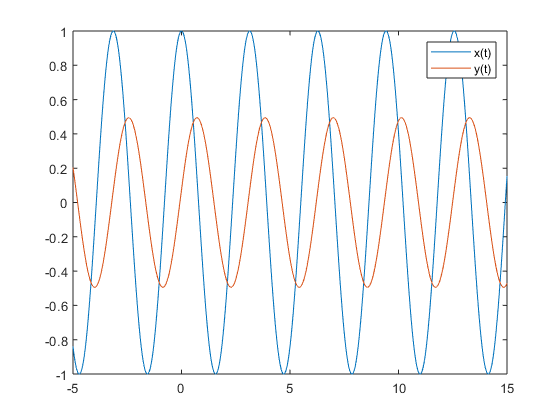

H = 1 / (a + 1j * w); % H(w)
y = abs(H) * cos(w*t + angle(H)); % transfer function theory
plot(t,x, t,y), legend('x(t)', 'y(t)')

Now, let's calculate the system output using anther method, convolution directly.

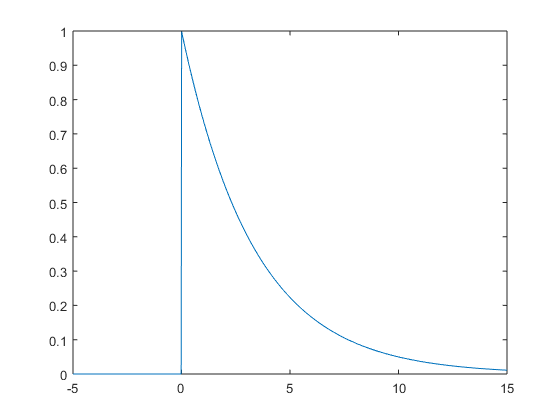

h = exp(-a*t) .* (t>0);
plot(t,h)

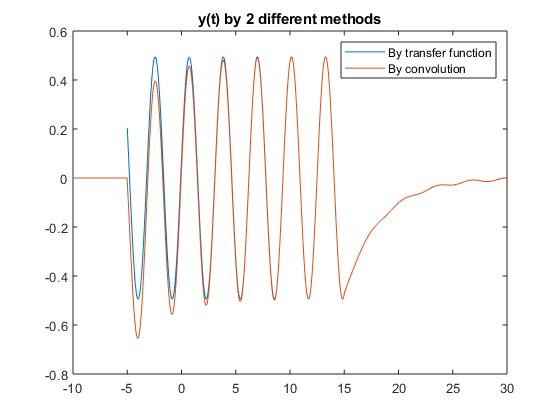

dt = diff(t(1:2));
y2 = conv(x,h)*dt; % Riemann convolution integral
ty2 = linspace(2*t(1), 2*t(end), length(t)*2-1); % width property
plot(t,y, ty2,y2)
title('y(t) by 2 different methods')
legend('By transfer function', 'By convolution')

These approaches agree in the central portion. Note that convolution diverges from the correct result at the edge. The main reason for this is that the input x(t) is implicitly taken as 0 outside the range where it is defined (t values). Additionally, there is some error since the right tail of h(t) is truncated.